使用理论方法计算场分布

作者：FTT

创建日期：2024.12.10

clear
clc
close all

参数定义

delta = 0; %相对速度差
alpha = 0.05; %调制强度
Omega = 0.07 * 1e9; %调制频率
omega = 1 * 1e9; %输入频率
eps1 = 1;
eps0 = 8.854e-12;
c = 3e8;
cg = (1 + delta) * c / sqrt(eps1);
g = Omega / cg; %调制空间频率
X = linspace(0, 2 * pi / g, 5000); %表示共动坐标系下（确定x）的位置

通过有限光速介质（$\delta=0
$）在出射表面处的强度分布，距离$\tau=150$

tau = 37.5;
UA = exp(-g * (2 + delta) * alpha * sin(g * X) * tau - (delta + alpha * cos(g * X)) .^ 2/2 / alpha ^ 2 * (-1 - 2 * alpha * g * tau + exp(2 * alpha * g * tau)) ...
    +delta * (delta + alpha * cos(g * X)) * 2 / alpha ^ 2 * (-1 - alpha * g * tau + exp(alpha * g * tau)));

绘制共动坐标系下的强度分布

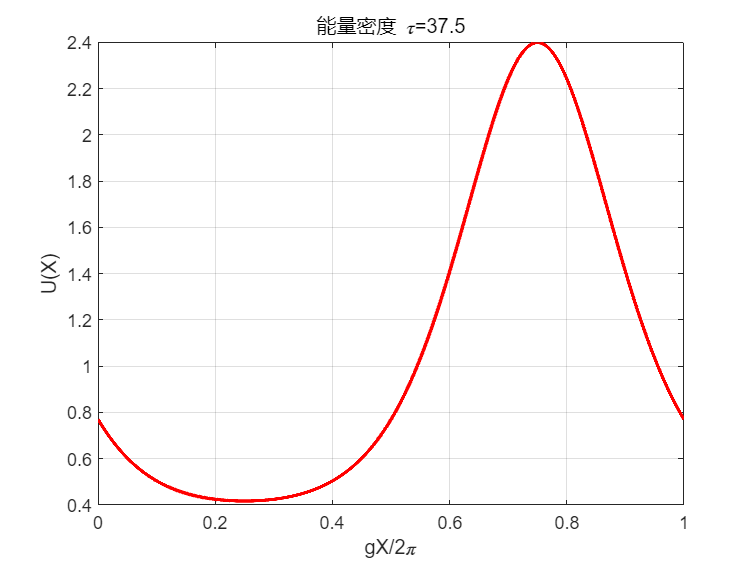

h1 = figure;
plot(g * X / 2 / pi, UA, 'r-', 'LineWidth', 2)
xlim([0 1])
xlabel('gX/2\pi')
ylabel('U(X)')
grid on
title('能量密度 \tau=37.5')

经过较长时间传播后的结果，$\tau = 600$

tau = 150;
UB = exp(-g * (2 + delta) * alpha * sin(g * X) * tau - (delta + alpha * cos(g * X)) .^ 2/2 / alpha ^ 2 * (-1 - 2 * alpha * g * tau + exp(2 * alpha * g * tau)) ...
    +delta * (delta + alpha * cos(g * X)) * 2 / alpha ^ 2 * (-1 - alpha * g * tau + exp(alpha * g * tau)));

绘制共动坐标系下的强度分布

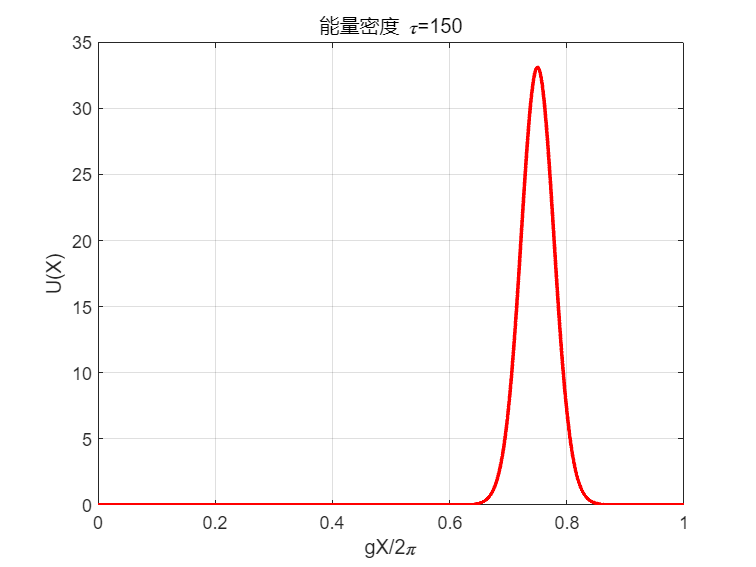


h2 = figure;
plot(g * X / 2 / pi, UB, 'r-', 'LineWidth', 2)
xlim([0 1])
xlabel('gX/2\pi')
ylabel('U(X)')
grid on
title('能量密度 \tau=150')

电场振幅，使用强度和相位组合，$\tau = 600$

tau = 150;
eps = eps1 * (1 + 2 * alpha * cos(g * X));
absE = sqrt(UB ./ eps / eps0); %场的模
btau = 1 / sqrt(-1/4 -1/2 * alpha * g * tau +1/4 * exp(2 * alpha * g * tau));
k1 = omega / c / sqrt(eps1);
x0tau = (g * X - 3 * pi / 2) / btau;
phaseE = k1 * exp(-g * alpha * sin(g * X) * tau) .* sqrt(pi) / 2 / g * btau .* (1 + erf(x0tau));
E = absE .* exp(1i * phaseE);

绘制共动坐标系下的电场分布

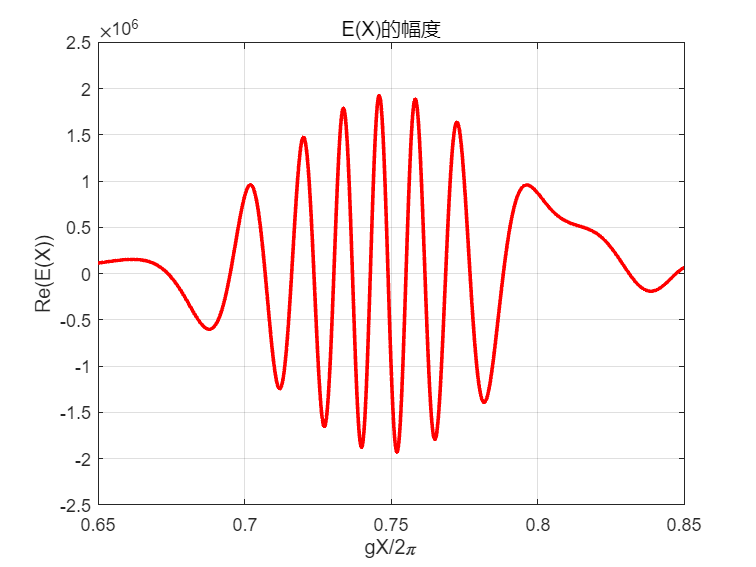

h3 = figure;
plot(g * X / 2 / pi, real(E(:)), 'r-', 'LineWidth', 2)
xlim([0.65, 0.85])
ylim([-2.5e6, 2.5e6])
xlabel('gX/2\pi')
ylabel('Re(E(X))')
grid on
title('E(X)的幅度')

$\delta\neq
0
$，$\tau = 600$ 情况下的强度分布

tau = 150;
UD = zeros(5, length(X));
deltalist = [-0.05, -0.025, 0, 0.025, 0.05];

for i = 1:length(deltalist)
    delta = deltalist(i);
    cg = (1 + delta) * c / sqrt(eps1);
    g = Omega / cg; %调制空间频率
    X = linspace(0, 2 * pi / g, 5000);
    UD(i, :) = exp(-g * (2 + delta) * alpha * sin(g * X) * tau - (delta + alpha * cos(g * X)) .^ 2/2 / alpha ^ 2 * (-1 - 2 * alpha * g * tau + exp(2 * alpha * g * tau)) ...
        +delta * (delta + alpha * cos(g * X)) * 2 / alpha ^ 2 * (-1 - alpha * g * tau + exp(alpha * g * tau)));

end

绘制共动坐标系下的强度分布

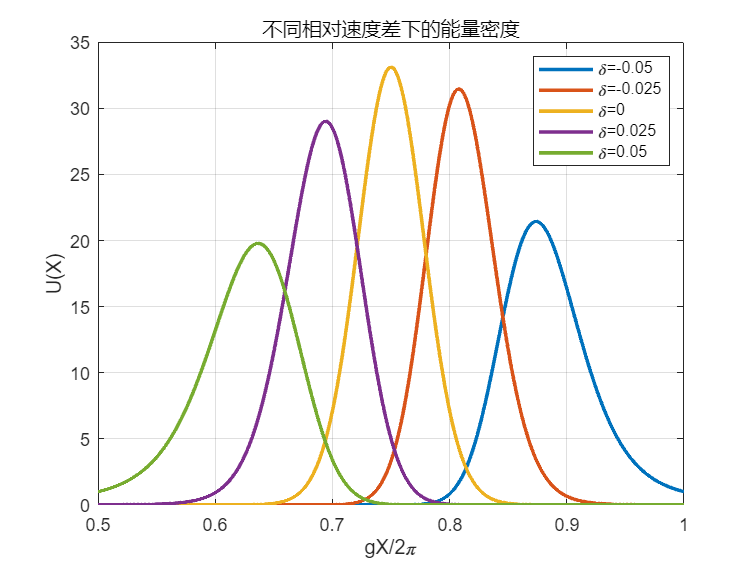

h4 = figure;
plot(g * X / 2 / pi, UD, 'LineWidth', 2)
xlim([0.5 1])
xlabel('gX/2\pi')
ylabel('U(X)')
grid on
legend('\delta=-0.05', '\delta=-0.025', '\delta=0', '\delta=0.025', '\delta=0.05')
title('不同相对速度差下的能量密度')